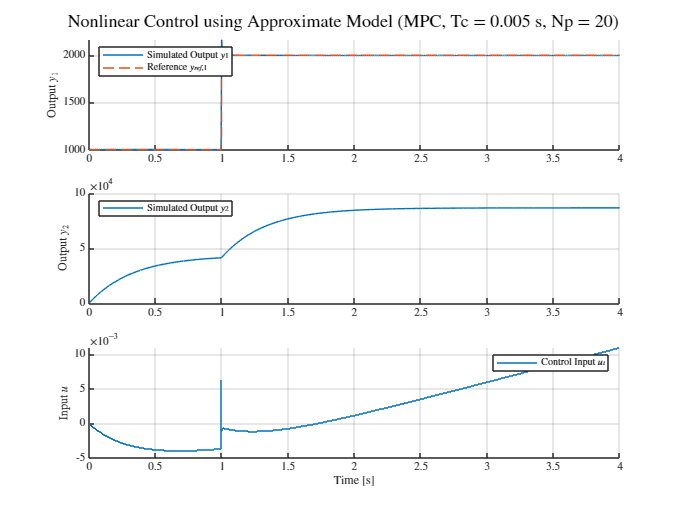

clear
rng(203829)
addpath('functions') % Make sure your functions F_ct, dF_ct, G_ct are accessible
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];
plotPos2 = [100 100 800, 600];

% System Parameters
kappa = 5*10^-5;
lambda = 3;
Lambda = 5*10^-5;
beta = 0.0065;
H = 0.05;
C0 = [1,0,0]; % Old Output matrix C
C = [1, 0, 0; 0, 1, 0]; % New Output matrix C (measuring states 1 and 2)

n_states = size(C, 2); % Number of states (should be 3)
n_outputs = size(C, 1); % Number of outputs (will be 2)

dt = 10^-3;   % Simulation/Euler time step



% Discrete-time approximate system functions (Euler step at dt)
function x_next = f_approx(x0, step_dt) % Use step_dt as argument name
    x_next = x0 + F_ct(x0) * step_dt;
end


% Simulation Parameters
x0 = [1000,0,beta]'; % Initial state
% x0 = [0,0, beta]';
Tfinal = 4;         % total simulation time [s]
Ts_sim = dt;            % Simulation sampling time
N_sim = round(Tfinal / Ts_sim); % number of simulation steps

% Controller Parameters
Tc = 0.005; % Controller time step [s] (Example: 5 ms) - Increased from 0.001 for demonstration
M = round(Tc / Ts_sim); % Number of simulation steps per controller step
if abs(M * Ts_sim - Tc) > 1e-9
    error('Controller timestep Tc must be a multiple of simulation timestep dt');
end
Np = 20; % Prediction horizon (in controller steps)
Nc = Np; % Control horizon (usually Nc <= Np)

% Tuning parameters
Q_u = 10^-3 * eye(Nc); % Control input weighting matrix for ||U_N||^2 (tune this)
Q_y = eye(Np * 1); % Output weighting matrix for ||Y_N - Y_ref_N||^2 (size Np*n_outputs x Np*n_outputs)


% Reference Trajectory (example: step change for both outputs)
y_ref_sim = x0(1)*ones(1, N_sim + 1);

step_time = 1;
step_sim_idx = round(step_time / Ts_sim);
% Step change for output 1
y_ref_sim(step_sim_idx:end) = x0(1) * 2; 


% Data storage
x_sim     = [x0, zeros(n_states, N_sim)];   % true state
y_sim     = zeros(n_outputs, N_sim + 1);     % measurements (y(t) corresponds to x(:,t))
u_sim     = zeros(1, N_sim);         % control inputs (applied at each sim step)
z_sim     = [x0, zeros(n_states, N_sim)];   % Unforced trajectory storage (for plotting open loop z)

% Initial output
y_sim(:, 1) = C * x_sim(:,1);
z_sim(:,1) = x_sim(:,1); % z0 = x0

current_u = 0; % Variable to hold the control input constant over Tc

% Simulation loop (runs at dt)
for t_sim_step = 1:N_sim

    % --- Controller Calculation (runs every Tc) ---
    if mod(t_sim_step - 1, M) == 0 % Check if it's the start of a new controller interval
        % t_ctrl_step = (t_sim_step - 1) / M + 1; % Current controller step index (1-based)

        % Current state for MPC is x_sim(:, t_sim_step)
        current_state = x_sim(:, t_sim_step);

        % 1. Compute the unforced trajectory z_t over the prediction horizon (in Tc steps)
        % z_horizon(:, k+1) represents z(t_ctrl + k*Tc) for k=0..Np
        z_horizon = zeros(n_states, Np + 1);
        z_horizon(:, 1) = current_state; % z(t_ctrl) = current state x(t_ctrl)

        z_current_Tc = current_state;
        for k = 1:Np
            % Predict z(t_ctrl + k*Tc) by taking M steps of Ts_sim from z(t_ctrl + (k-1)*Tc)
            z_next_Tc = z_current_Tc;
            z_horizon(:, k + 1) = f_approx(z_next_Tc, Tc);
            z_current_Tc = z_next_Tc;
        end

        % 2. Compute time-varying linearized matrices A_k, B_k along z_horizon (over Tc)
        % A_k (slide 8) = A_Tc(z(t_ctrl + k*Tc))
        % B_k (slide 8) = B_Tc(z(t_ctrl + k*Tc))
        A_horizon_Tc = zeros(n_states, n_states, Np); % A_k for k=0..Np-1
        B_horizon_Tc = zeros(n_states, 1, Nc);    % B_k for k=0..Nc-1 (B_k is 3x1 vector)

        for k = 0:(Np-1)
            state_at_k_Tc = z_horizon(:, k + 1); % z(t_ctrl + k*Tc)
            A_Tc = eye(n_states) + dF_ct(state_at_k_Tc) * Tc;
            B_Tc = G_ct(state_at_k_Tc) * Tc;

            A_horizon_Tc(:, :, k + 1) = A_Tc; % Store as A_k (slide index k=0..Np-1)
            if k < Nc
                 B_horizon_Tc(:, :, k + 1) = B_Tc; % Store as B_k (slide index k=0..Nc-1), B_k is 3x1
            end
        end

        % 3. Build Gamma_yu^Np and Y_z (using A_Tc, B_Tc matrices)
        Gamma_yu = zeros(Np, Nc); % Output matrix Gamma_yu^Np (Np*n_outputs rows, Nc cols)
        Y_z_vec = zeros(Np, 1); % Stacked C*z_{t_ctrl+i*Tc}

        % Build Y_z vector
        for i_row = 1:Np % Row index for outputs (corresponds to y_{t_ctrl+i_row*Tc})
             Y_z_vec((i_row-1) + 1 : i_row, 1) = C0 * z_horizon(:, i_row + 1);
        end

        % Build Gamma_yu matrix
        % Gamma_yu block (i_row, j_col) for output y_{t_ctrl+i_row*Tc} and input u_{t_ctrl+(j_col-1)*Tc}
        % is C * Phi(i_row, j_col) * B_{j_col-1} if i_row >= j_col
        % Phi(i_row, j_col) = A_{i_row-1} * ... * A_{j_col} (slide indices)
        % A_k (slide index) is A_horizon_Tc(:, :, k+1)
        % B_k (slide index) is B_horizon_Tc(:, :, k+1)

        for i_row = 1:Np % Block row index for Gamma_yu (corresponds to y_{t_ctrl+i_row*Tc})
            for j_col = 1:Nc % Column index for Gamma_yu (corresponds to u_{t_ctrl+(j_col-1)*Tc})
                if i_row >= j_col
                    % Calculate Phi(i_row, j_col) = A_{i_row-1} * ... * A_{j_col} (slide indices)
                    % Product is A_horizon_Tc(:,:, i_row) * A_horizon_Tc(:,:, i_row-1) * ... * A_horizon_Tc(:,:, j_col+1)
                    Phi = eye(n_states);
                    for k_prod = i_row:-1:(j_col+1)
                         % A_{k_prod-1} (slide index) is A_horizon_Tc(:,:, k_prod)
                         Phi = A_horizon_Tc(:, :, k_prod) * Phi;
                    end
                    % B_{j_col-1} (slide index) is B_horizon_Tc(:, :, j_col)
                    % The block C * Phi * B is size n_outputs x 1
                     Gamma_yu((i_row-1) + 1 : i_row, j_col) = C0 * Phi * B_horizon_Tc(:, :, j_col);
                else
                    % Gamma_yu block is 0 if i_row < j_col
                    % (The columns j_col > i_row remain zero from initialization)
                end
            end
        end

        % 4. Define the reference trajectory for the horizon
        % We need y_ref for times t_ctrl+Tc, t_ctrl+2Tc, ..., t_ctrl+Np*Tc
        ref_sim_indices = t_sim_step + (1:Np) * M;
        % Ensure indices do not exceed simulation bounds
        ref_sim_indices = min(ref_sim_indices, N_sim + 1);
        y_ref_horizon_vec = y_ref_sim(:, ref_sim_indices); % Size n_outputs x Np
        y_ref_horizon_vec = y_ref_horizon_vec(:); % Reshape to column vector (Np*n_outputs x 1)

        % 5. Formulate the optimization problem and solve for U_N
        % Minimize || Y_z_vec + Gamma_yu U_N - y_ref_horizon_vec ||_{Q_y}^2 + || U_N ||_{Q_u}^2
        % U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u)^-1 * Gamma_yu' * Q_y * (y_ref_horizon_vec - Y_z_vec)

        % Calculate the target for the input contribution
        Y_error = y_ref_horizon_vec - Y_z_vec;

        % Solve for U_N = [u_{t_ctrl}; u_{t_ctrl+Tc}; ...; u_{t_ctrl+(Nc-1)Tc}]
        % Add a small term for numerical stability
        stability_term = 1e-12 * eye(Nc); % Smaller regularization
        U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u + stability_term) \ (Gamma_yu' * Q_y * Y_error);

        % 6. Apply the first control input (will be held constant for M steps)
        current_u = U_N(1);

        % Store the calculated U_N (optional, useful for debugging/analysis)
        % U_ctrl_hist(:, t_ctrl_step) = U_N;
    end % End of controller calculation block

    % --- Simulate the true nonlinear system (runs at dt) ---
    % Use the current_u which is constant over the Tc interval
    f_val = F_ct(x_sim(:, t_sim_step));
    g_val = G_ct(x_sim(:, t_sim_step));

    % Euler step for simulation (sticking to Euler for consistency with approximation)
    x_sim(:, t_sim_step + 1) = x_sim(:, t_sim_step) + f_val * Ts_sim + g_val * current_u * Ts_sim;

    % Store applied control input (repeats the value for M steps)
    u_sim(t_sim_step) = current_u;

    % Measure the output
    y_sim(:, t_sim_step + 1) = C * x_sim(:, t_sim_step + 1);

    % Update open-loop unforced trajectory (for plotting z_t only, runs at dt)
    z_sim(:, t_sim_step + 1) = f_approx(z_sim(:, t_sim_step), Ts_sim);

end % End of simulation loop

% --- Plotting ---
figure('Position', plotPos2);
% Plot each output separately
subplot(n_outputs + 1, 1, 1);
hold on;
plot((0:N_sim)*Ts_sim, y_sim(1, :), 'DisplayName', 'Simulated Output $y_1$');
plot((0:N_sim)*Ts_sim, y_ref_sim(1, :), '--', 'DisplayName', 'Reference $y_{ref,1}$');
ylabel('Output $y_1$');
legend('Location', 'northwest');
grid on;
hold off;

subplot(n_outputs + 1, 1, 2);
hold on;
plot((0:N_sim)*Ts_sim, y_sim(2, :), 'DisplayName', 'Simulated Output $y_2$');
ylabel('Output $y_2$');
legend('Location', 'northwest');
grid on;
hold off;

% Plot input
subplot(n_outputs + 1, 1, n_outputs + 1);
hold on;
stairs((0:N_sim-1)*Ts_sim, u_sim, 'DisplayName', 'Control Input $u_t$');
ylabel('Input $u$');
xlabel('Time [s]');
legend('Location', 'northeast');
grid on;
hold off;

sgtitle(sprintf('Nonlinear Control using Approximate Model (MPC, Tc = %.3f s, Np = %d)', Tc, Np));

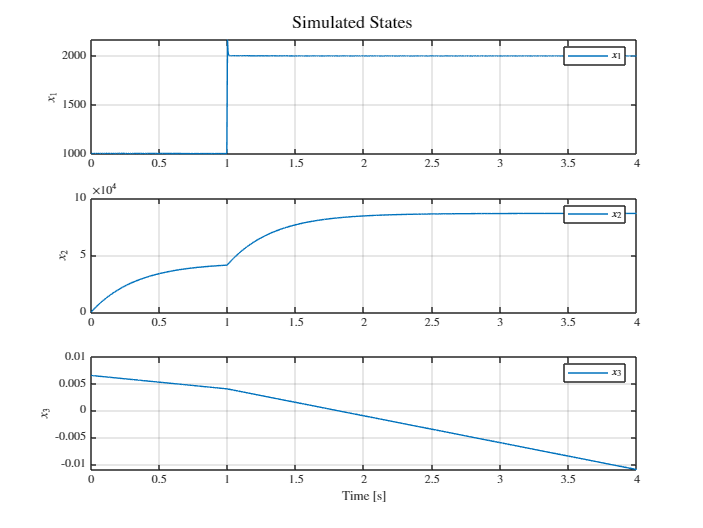


% Optional: Plot states
figure('Position', plotPos2);
subplot(3,1,1);
plot((0:N_sim)*Ts_sim, x_sim(1,:)); ylabel('$x_1$'); grid on; legend('$x_1$');
subplot(3,1,2);
plot((0:N_sim)*Ts_sim, x_sim(2,:)); ylabel('$x_2$'); grid on; legend('$x_2$');
subplot(3,1,3);
plot((0:N_sim)*Ts_sim, x_sim(3,:)); ylabel('$x_3$'); xlabel('Time [s]'); grid on; legend('$x_3$');
sgtitle('Simulated States');